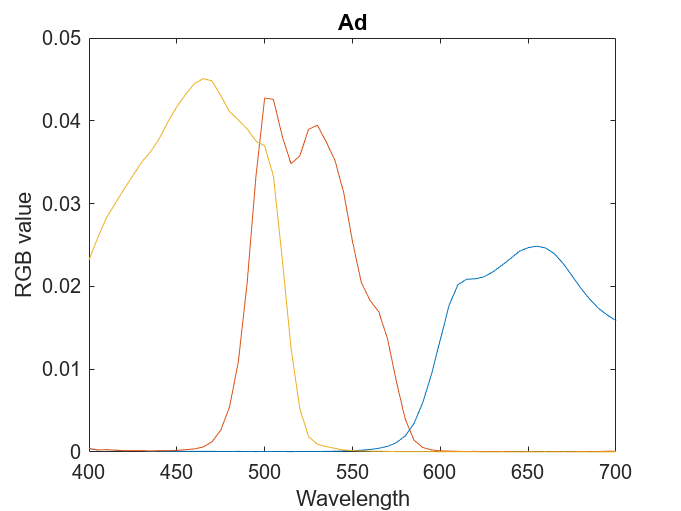

clear
clf

% 1.1
load("Ad.mat");
load("Ad2.mat");

wavelength = 400:5:700;

plot(wavelength, Ad);
title("Ad")
xlabel("Wavelength")
ylabel("RGB value")

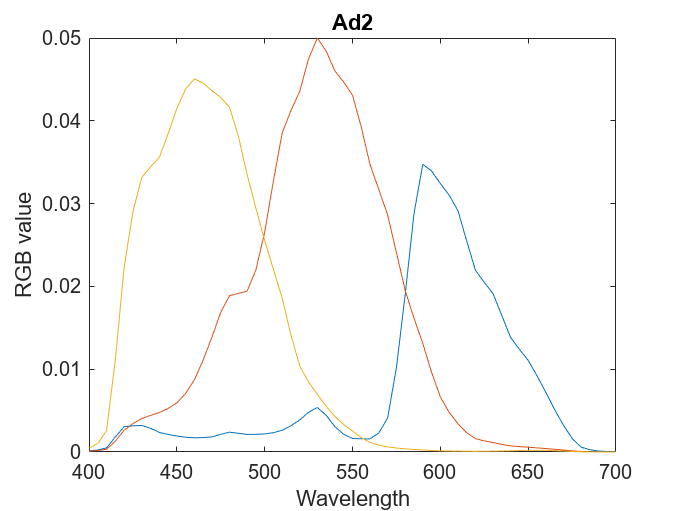


plot(wavelength, Ad2);
title("Ad2")
xlabel("Wavelength")
ylabel("RGB value")

**Answer:** No, it should not have the same output as the curves are different. Looking at wavelengths toward 700 for example, the first camera should display a **very red output while the second camera shows close to nothing. rewrite this**

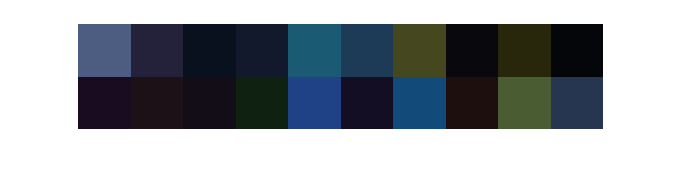

% 1.2
load("chips20.mat");
load("illum.mat");

% vad gör vi här
RGB_raw_D65 = Ad' * (chips20 .* CIED65)';
showRGB(RGB_raw_D65')

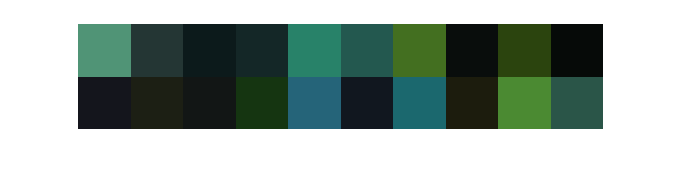


% igen
RGB_raw_D652 = Ad2' * (chips20 .* CIED65)';
showRGB(RGB_raw_D652')

% enligt instruktion ska vi tycka att det behövs kalibrering

**Answer:** ?

% 2.1
e = ones(1,61);
k = Ad' * e';
k = 1./k

k =     2.1574
    1.7711
    1.1649


k2 = Ad2' * e';
k2 = 1./k2

k2 =     2.1161
    1.1433
    1.3476


**Answer:** We think it makes sense. All the RGB values get scaled up, but those with lower values have a higher factor to make them closer to the rest. The original images do not have much red, but the red values are scaled up more than the others.

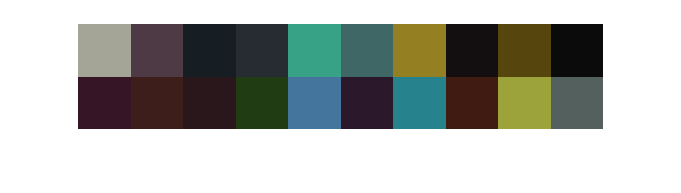

% 2.2
RGB_cal_D65 = RGB_raw_D65.*k;
RGB_cal_D652 = RGB_raw_D652.*k2;

showRGB(RGB_cal_D65')

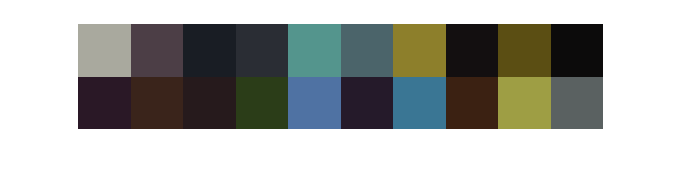

showRGB(RGB_cal_D652')

**Answer:** The results look a lot more stable with more varying colors.

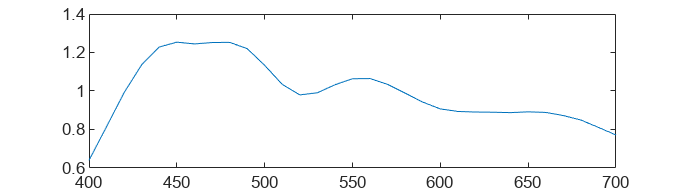

% 2.3
plot(wavelength, CIED65) % Outdoor

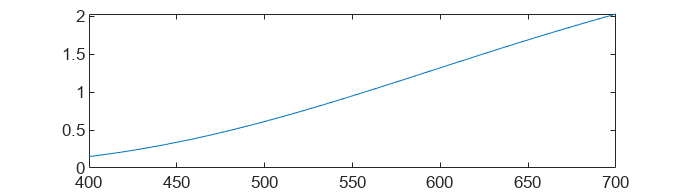

plot(wavelength, CIEA) % Indoor

**Answer:** Outdoor light is a lot more even with light of all wavelengths.

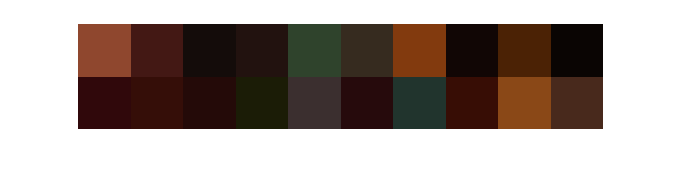

% 2.4
RGB_raw_A = Ad' * (chips20 .* CIEA)';
showRGB(RGB_raw_A')

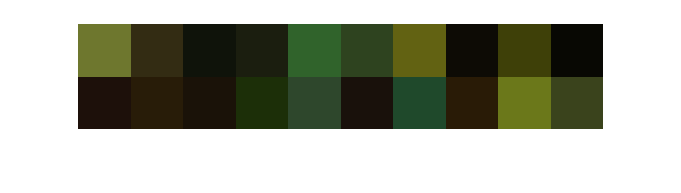


RGB_raw_A2 = Ad2' * (chips20 .* CIEA)';
showRGB(RGB_raw_A2')

**Answer:** The light affects the color. CIEA is more of a "red light" and contributes to a higher R value.

% 2.5
% New calibration factors
R = ones(1,61);
k = Ad' * R';
k = 1./k

k =     2.1574
    1.7711
    1.1649


k2 = Ad2' * R';
k2 = 1./k2

k2 =     2.1161
    1.1433
    1.3476



% CIED65
RGB_cal_D65 = RGB_raw_D65.*k;
RGB_cal_D652 = RGB_raw_D652.*k2;

showRGB(RGB_cal_D65')

showRGB(RGB_cal_D652')

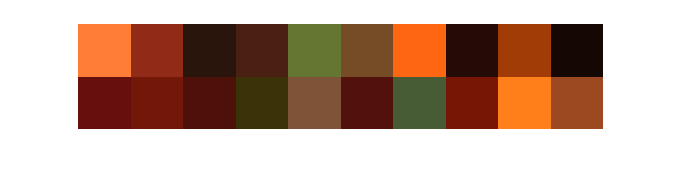


% CIEA
RGB_cal_A = RGB_raw_A.*k;
RGB_cal_A2 = RGB_raw_A2.*k2;

showRGB(RGB_cal_A')

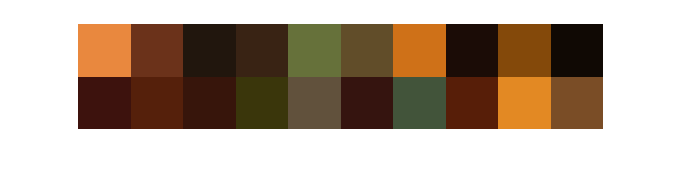

showRGB(RGB_cal_A2')

**Answer:** D65 does not have a difference compared to before as the light is "colorless", but for A where the light is more red, the red colors become more intense.